# Frequency Spectrum

### Define parameters: latitude, stratification, local depth

%Stratification
N0 = 3*2*pi/3600;
L_gm = 1300;
N2Func = @(z) N0*N0*exp(2*z/L_gm);
latitude=33;

%Depth
Lz=4000;  

### Initialize the function

tic
im = InternalGravityWaveSpectrum(N2Func,Lz,nModes=64);
toc

### Verify vertical variace

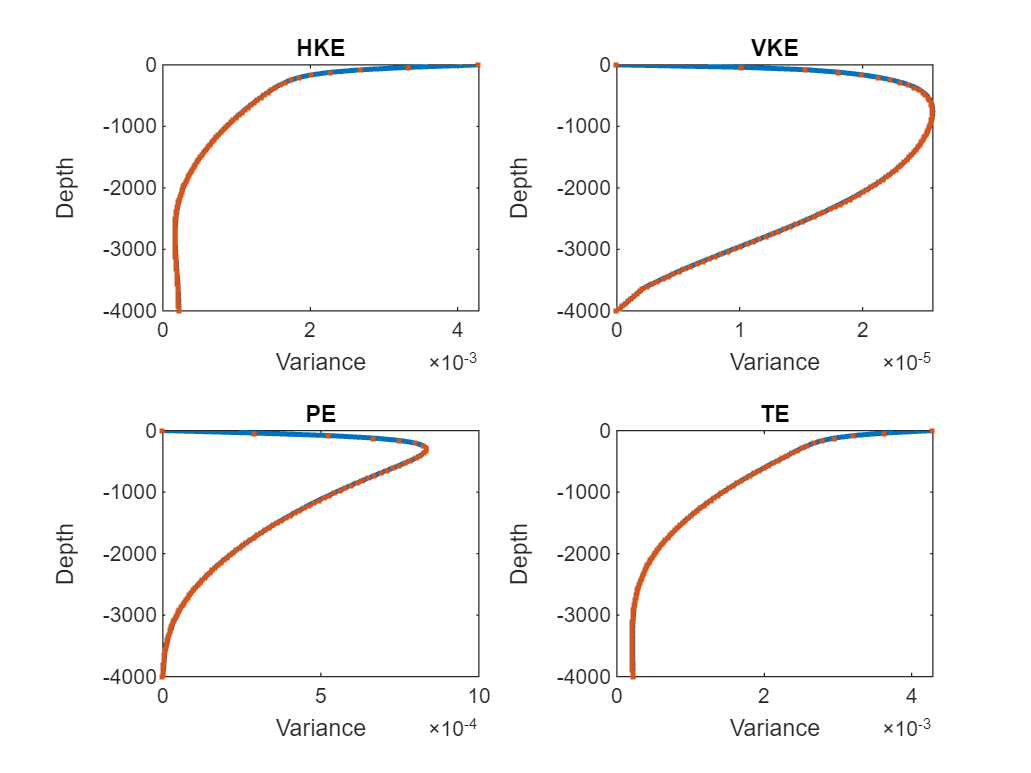

zvect = linspace(-im.Lz, 0, 100); 
energyComp = {'HKE','VKE','PE','TE'};

% Create a figure with 4 subplots
clf
figure;

% Loop over each energy component
for idx = 1:length(energyComp)
   
    energyVariance = im.verticalVariance(energyComp{idx}, 'zVector', zvect, 'Plot', 0);    
    
    energyVarianceFreq = zeros(1, length(zvect));
    for i = 1:length(zvect)
        [S,~]=im.energyAtFrequencies(energyComp{idx}, zvect(i), 'Plot', 0);
        energyVarianceFreq(i) = sum(S);
    end
    
    % Plot the variance in a subplot
    subplot(2, 2, idx);
    plot(energyVariance, zvect, LineWidth=2);
    hold on
    plot(energyVarianceFreq,zvect,'.')

    title(energyComp{idx});  
    xlabel('Variance');       
    ylabel('Depth');          

end

### Number of modes per frequency

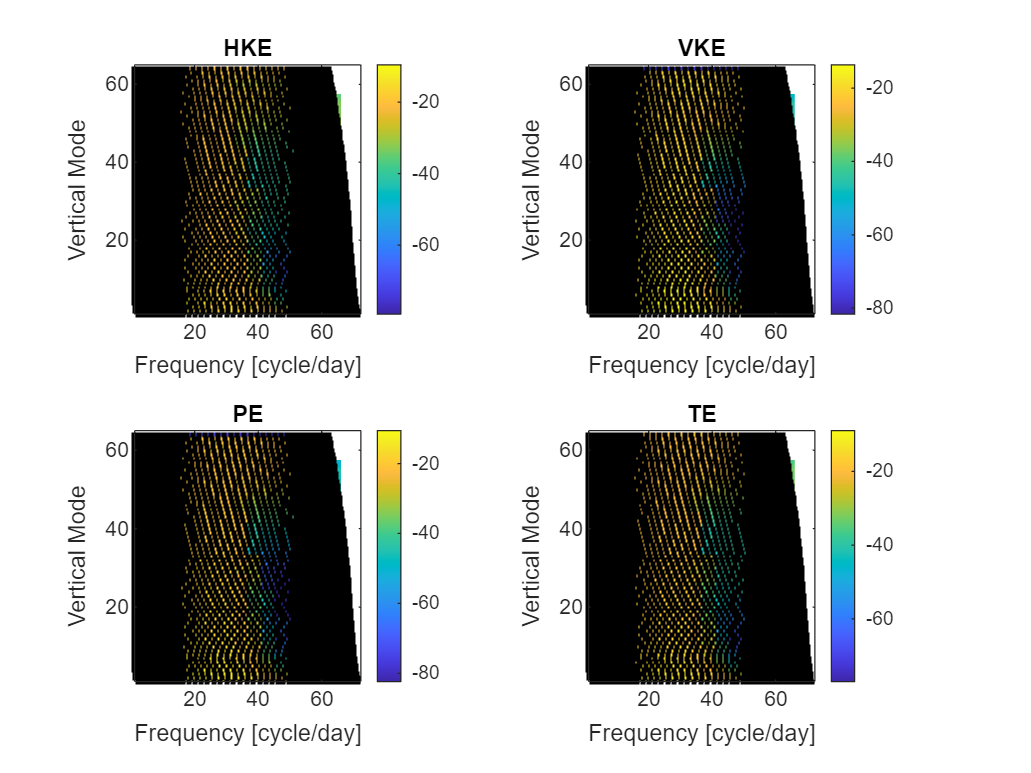

% Define energy components
energyComp = {'HKE','VKE','PE','TE'};

% Initialize figure
clf;

% Loop through each energy component
for i = 1:length(energyComp)
    % Call im.energyAtFrequencies with current energy component
    [S, energyFrequency] = im.energyAtFrequencies(energyComp{i}, -1000, 'Plot', 0);
    
    % Create subplot for each energy component
    subplot(2, 2, i);  % 2x2 grid of panels

    % Define X and Y
    X = (im.omegaVector * 24 * 3600) / (2 * pi);
    Y = im.j;

    % Plot energy frequency
    jpcolor(X, Y, log(energyFrequency));
    shading flat;
    colorbar;

    % Label axes
    xlabel('Frequency [cycle/day]');
    ylabel('Vertical Mode');

    % Title for each subplot based on the energy component
    title(energyComp{i});

    J =repmat(im.j',1,im.nK);
    omegajK = im.omega;

    % Overlay black dots where isRepresented matrix has ones
    % hold on;
    % [row, col] = find(isRepresented >= 1);
    % plot(X(col), Y(row), '.k');
    hold on
    scatter((omegajK*24*3600)/(2*pi),J,'k',Marker='.');


    
end

### Max stratification in the toolbox

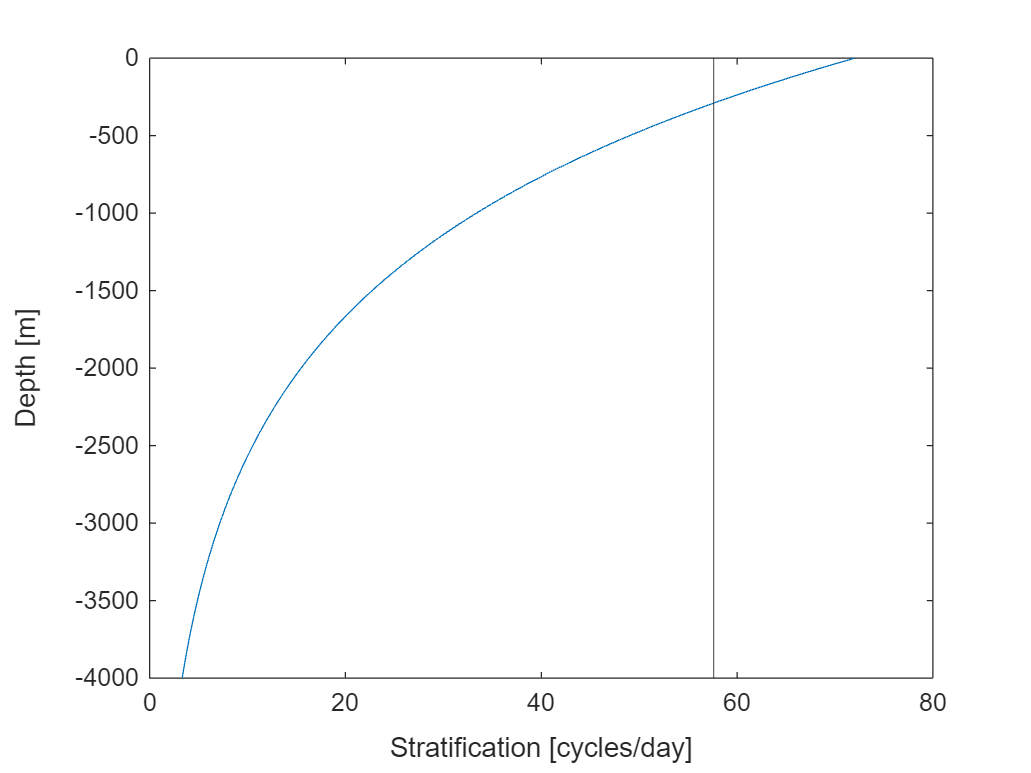

clf
plot((sqrt(im.N2(zvect))*24*3600)/(2*pi),zvect)
hold on
xline(((sqrt(im.N2max))*24*3600*0.8)/(2*pi))

xlabel("Stratification [cycles/day]")
ylabel("Depth [m]")

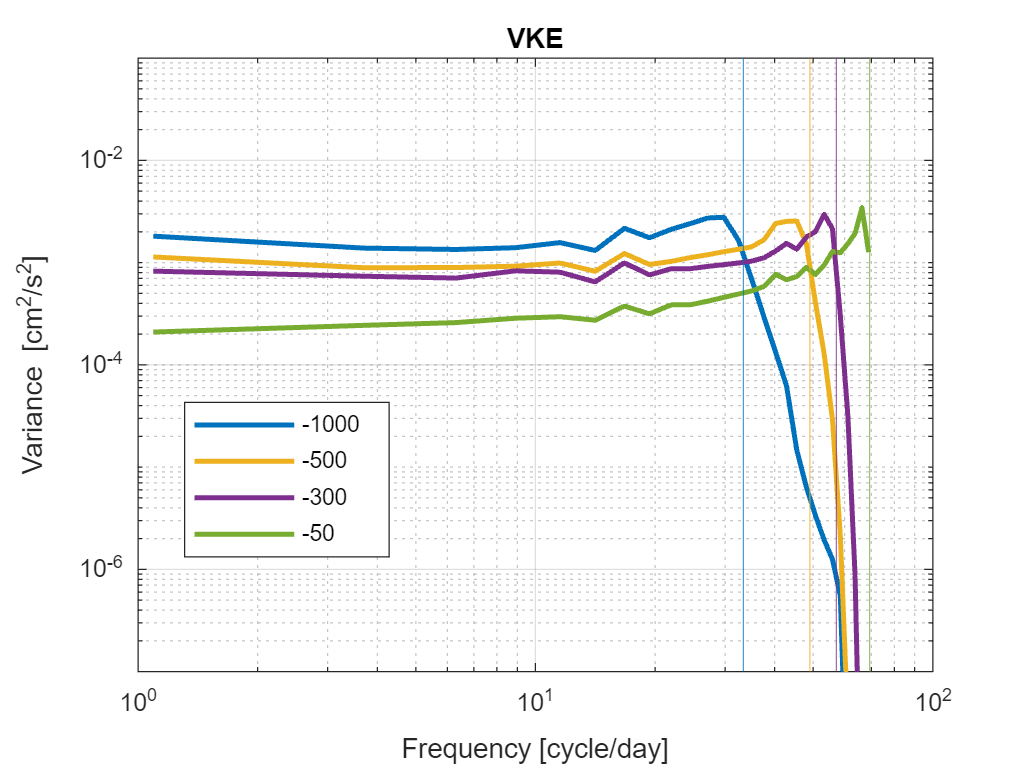

zvect2 = [-1000,-500,-300,-50]; 
colors=["#0072BD","#EDB120","#7E2F8E","#77AC30"];

clf
for i = 1:length(zvect2)

        [S,~]=im.energyAtFrequencies('VKE',zvect2(i),plot=0);
        loglog((im.omegaVector)*(24*3600)/(2*pi), S*1000,Color=colors(i),LineWidth=2) 
        hold on        
end

legend(num2str(zvect2(1)),num2str(zvect2(2)),num2str(zvect2(3)),num2str(zvect2(4)))
ylim([10^-7,10^-1])

for i = 1:length(zvect2)
        xline((sqrt(im.N2(zvect2(i)))*24*3600)/(2*pi),"Color",colors(i),'HandleVisibility', 'off');
        title('VKE')
        ylabel("Variance [cm^2/s^2]")
        xlabel("Frequency [cycle/day]")
        grid on
end

# Wave Vortex Model

%%%% DOMAIN
N = 64;
aspectRatio = 1;

Lx = 100e3;
Ly = aspectRatio*100e3;

Nx = N;
Ny = aspectRatio*N;
Nz = 128+1; % 2^n + 1 grid points, to match the Winters model, but 2^n ok too.


wvt = WVTransformBoussinesq([Lx, Ly, Lz], [Nx, Ny, Nz], latitude=latitude, N2=N2Func);

wvt.initWithAlternativeSpectrum;

[energyFrequency,omegaVector] = wvt.convertFromWavenumberToFrequency;
energyFrequencyDepth = 

### Comparing WVM with the IGWS